# Summary Data

## First get time per Chamber

animalIDs=ls('*3chamber*');

sessions={'hab', 'cups', 'fam1', 'nov','fam2'};
yy=size(animalIDs);


load('evs_matrix.mat')
load('R')
timeStamps=cell2mat(R.TimeStamps)';

pos_ss=R.Pos.t(1:1:end);

    for r=1:length(timeStamps)
        q= pos_ss;
        val(r) = timeStamps(r); %value to find
        
    end
    
    closest_ind=ones(1,length(timeStamps));
    for aa=1:length(timeStamps)
        tmp = abs(q-val(aa));
        [idx idx]= min(tmp); %index of closest value
        closest_ind(aa)=idx;
    end
    
numSess=input('how many sessions?');
Start=ones(1,5);End=ones(1,5);
for aa=1:numSess
    Start(aa)=closest_ind(2*aa-1);
    End(aa)=closest_ind(2*aa);
end

Labels=zeros(1,length(pos_ss));
    for aa=1:numSess
        Labels(Start(aa):End(aa))=aa;
    end
    
    clearvars -except Labels evs_matrix

Average Path Length and Velocity

    for hh=1:yy(1)
        cd(animalIDs(hh,1:end))
        load('R')
        list_cells=num2str(ls('TT*unit*'));
        cd(list_cells(1,1:end))
        load('Split.mat')
        for jj=1:length(sessions)
            thisSession=sessions(jj);
            thisSession=cellstr(thisSession);
            thisSession=char(thisSession);
            posx=eval(strcat('Split.',thisSession,'.posx'));
            posy=eval(strcat('Split.',thisSession,'.posy'));
            post=eval(strcat('Split.',thisSession,'.post'));
            d = hypot(diff(posx), diff(posy));   
            Path_Length(hh,jj)=sum(d);
            mean_vel(hh,jj)=mean(speed2D(posx,posy,post));
            
            
            
        end
        cd ..;cd ..
    end
    

Mean FR

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
       list_cells=num2str(ls('TT*unit*'));
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        load('map.mat')
        meanFR(j)=nanmean(nanmean(map));
        clear map
        cd ..

    end
        
    cd .. 
    avFR{hh}=meanFR';
    clear meanFR
end
avFR_all=vertcat(avFR{:});

p.binWidth = 1;
p.smoothing = 2;
p.smoothValues = [1.5, 3.0, 5.0, 7.5, 10, 15, 20, 30];
p.minNumBins = 9;
p.maxNumBins= 500;
p.fieldTreshold = .4;
p.lowestFieldRate = 2;
p.trajmap = 1;
p.plotratemap = 1; 
p.gridscore = 1;
p.lowSpeedThreshold = 1; 
p.highSpeedThreshold = 0; % [cm/s]
p.imageDir = 'CorrelationImages\';
R.p=p;

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
       list_cells=num2str(ls('TT*unit*'));
       load('R.mat')
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        try
        load('Split')        
        for k=1:length(sessions)
        thisSession=sessions(k);
        thisSession=cellstr(thisSession); 
        thisSession=char(thisSession);
       
        posx=eval(strcat('Split.',thisSession,'.posx'));
        posy=eval(strcat('Split.',thisSession,'.posy'));
        post=eval(strcat('Split.',thisSession,'.post'));
        spkx=eval(strcat('Split.',thisSession,'.spkx'));
        spky=eval(strcat('Split.',thisSession,'.spky'));
        spkt=eval(strcat('Split.',thisSession,'.spkt'));
        
        
        velThresh=1;
        
        [~,spkx_mo,spky_mo,~] = filt_by_speed(posx,posy,post,spkx,spky,spkt,velThresh);
        [map,pospdf] = ratemap(spkx_mo,spky_mo,posx,posy,post,p.smoothing,R.mapAxis,R.mapAxis);
        map(R.visited==0) = NaN;
        p.maxNumBins=length(map)*length(map)/2;
        [nFields(j,k),fieldProp] = placefield(map,p,R.mapAxis);
        
        if nFields(j,k)~=0
        [info(j,k),~,selectivity(j,k)] = mapstat(map,pospdf);
        else
        info(j,k)=0;
        selectivity(j,k)=0;
        end
        
        if nFields(j,k)>0
            fieldProp=struct2cell(fieldProp);
            fieldProp=cell2mat(fieldProp);
            fs(j,k)=nanmean(fieldProp(5,:));
        else
            fs(j,k)=NaN;
        end
        
        end
        
        catch
        end
        cd ..
    end
    cd ..
    NumFields{hh}=nFields; Info{hh}=info; Selectivity{hh}=selectivity; 
    FieldSize{hh}=fs;
    clear -list_cells nFields info selectivity fs
    end


Social Responders

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
    list_cells=num2str(ls('TT*unit*'));
        for i=1:length(list_cells)
        cd(list_cells(i,1:end))
        load('Split.mat')
        for j=1:length(sessions)
            thisSession=sessions(j);
            thisSession=cellstr(thisSession);
            thisSession=char(thisSession);
            post=eval(strcat('Split.',thisSession,'.post'));
            ts=eval(strcat('Split.',thisSession,'.spkt'));
            FRs(i,j)=length(ts)/(post(end)-post(1));
        end
        cd ..
        end
        firingRates{hh}=FRs;
        clear FRs
        cd ..

end
firingRates=vertcat(firingRates{:});

asoc_FR=mean(firingRates(:,1:2)');
soc_FR=mean(firingRates(:,3:5)');
asoc_v_soc=horzcat(asoc_FR,soc_FR);
asoc_v_soc=horzcat(asoc_FR',soc_FR');

asoc_FR=mean(frnorm(:,1:2)');
soc_FR=mean(frnorm(:,3:5)');
asoc_v_soc_norm=horzcat(asoc_FR,soc_FR);
asoc_v_soc_norm=horzcat(asoc_FR',soc_FR');

HeatMaps/Spatial Correlations from when animals aren't moving

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
    list_cells=num2str(ls('TT*unit*'));
    load('R.mat')
    velThresh=1;
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        load('Split.mat')
        for j=1:length(sessions)
            thisSession=sessions(j);
            thisSession=cellstr(thisSession);
            thisSession=char(thisSession);
            posx=eval(strcat('Split.',thisSession,'.posx'));
            posy=eval(strcat('Split.',thisSession,'.posy'));
            post=eval(strcat('Split.',thisSession,'.post'));
            spkx=eval(strcat('Split.',thisSession,'.spkx'));
            spky=eval(strcat('Split.',thisSession,'.spky'));
            ts=eval(strcat('Split.',thisSession,'.spkt'));
            cd(thisSession); mkdir('immobile');cd('immobile')
            makeImPlots(posx, posy, post, spkx, spky, ts, R.mapAxis, R.p, R.visited, velThresh)
            cd ..;cd ..
        end
        cd ..
    end
cd ..
end

Spatial Correlations during immobility

%%correlations immobility
for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
    list_cells=num2str(ls('TT*unit*'));
    tic
    corr_mat=cell(length(list_cells),5);
    for i=1:length(list_cells)
        thisCell=list_cells(i,1:end);
        cd(thisCell)
        for j=1:length(sessions)
            thisSession=sessions{j};
            cd(thisSession); cd ('immobile')
            load('map.mat'); map(isnan(map))=[];
            corr_mat{i,j}=map;
            cd ..;cd ..
        end
        cd ..
    end
    toc
    
    save('corr_mat_im','corr_mat')
    sess_corr=zeros(length(corr_mat),(length(sessions)-1));
    p_vals=zeros(length(corr_mat),(length(sessions)-1));
    for ii=1:length(list_cells)
        for jj=1:length(sessions)-1
            sess1=corr_mat{ii,jj};
            sess2=corr_mat{ii,jj+1};
            [r,p]=corrcoef(sess1,sess2);
            pop_corr(ii,jj)=r(2,1);
            p_vals(ii,jj)=p(2,1);
        end
    end
    
    save('pop_corr_im','pop_corr')
    figure()
    for i=1:length(list_cells)
        plot(pop_corr(i,:))
        hold on
        axis([.5 4.5 -.5 1])
    end
    plot(mean(pop_corr),'k','linewidth',5)
    pc{hh}=pop_corr;
    clear pop_corr
    title('Spatial Corr by cell')
    cd ..
end



Spatial Correlations vs Field Size

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
    load('pop_corr.mat')
    corrs{hh}=pop_corr;
    clear pop_corr
    cd ..
end
    

    fs=vertcat(FieldSize{:});ps=vertcat(corrs{:});
    fs=reshape(fs(:,2:end),[],1);ps=reshape(ps,[],1);
    %%you want the y-intercept here- higher intercept means higher stability
    %%(giocomo et al 2011)
    [p,S]=polyfit(fs(~isnan(fs)&fs<500),ps(~isnan(fs)&fs<500),1);
    [fity,delta]=polyval(p,fs(~isnan(fs)&fs<500),S);

fitlm(fs,ps(1:length(fs)),'linear')

fitlm(fs,ps(1:length(fs)))

FR_all(isnan(FR_all))=0;
FR_all(FR_all==Inf)=0;
[p,S]=polyfit(FR_all(:,4),FR_all(:,3),1);
[fity,delta]=polyval(p,FR_all(:,4),S);

scatter(FRs(:,1),FRs(:,2),'k')
hold on
[p,S]=polyfit(FRs(:,1),FRs(:,2),1);
[fity,delta]=polyval(p,FRs(:,1),S);
plot(FRs(:,1),fity,'r')
%axis([0 max(FRs(:,2)) 0 max(FRs(:,2))])
fitlm(FRs(:,1),FRs(:,2))


rng('default')  % For reproducibility
y = FRs(:,1);



Mean FR and STD from habituation

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
       list_cells=num2str(ls('TT*unit*'));
       %load evs_matrix.mat
       makeEvsMatrix
        cd(list_cells(1,1:end))
        load('Split')
        habInds=Split.hab.times(1:end);
        hab_evs=evs_matrix(:,habInds);
        %%compute std with ~10 second bins
        
        for ii=1:length(list_cells)
            means(ii,:)=movmean(hab_evs(ii,:),300);
            stds(ii,:)=movstd(hab_evs(ii,:),300);
        end         
        cd ..
        save('hab_means','means');save('hab_stds','stds')

    cd ..
    clear means stds  

end

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
list_cells=num2str(ls('TT*unit*'));
%makeEvsMatrix
load('R.mat');load('cups.mat')
  

sessions={'hab','cups','fam1', 'nov', 'fam2'};
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        for k=1:length(sessions)
        thisSession=sessions(k);
        thisSession=cellstr(thisSession); 
        thisSession=char(thisSession);
        cd(thisSession)
        load('leftCup.mat');
        if isempty(leftCup{4})
            frL(j,k)=NaN;
        else
        %frL(j,k)=leftCup{7}/(length(leftCup{4}/30));
        %frL(j,k)=rightCup{7}/(length(rightCup{4}/30));
        frL(j,k)=leftCup{7}/((leftCup{4}(end)-leftCup{4}(1)));
        end
        %frL_norm(j,k)=(frL(j,k)-cup_means(j))/cups_std(j);
        cd ..
        end
        cd ..
        FRs{hh}=frL;
        
        
    end
    clearvars('frL_norm', 'frL','evs_matrix')
    cd ..
end

scatter(FR_all(:,3),FR_all(:,4),'k')
hold on
plot(0:7,0:7,'k')
fitlm(FR_all(:,3),FR_all(:,4))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.38191     0.096229    3.9687    0.00014608
    x1             0.87499     0.067942    12.878    4.8366e-22


Number of observations: 91, Error degrees of freedom: 89
Root Mean Squared Error: 0.757
R-squared: 0.651,  Adjusted R-Squared 0.647
F-statistic vs. constant model: 166, p-value = 4.84e-22

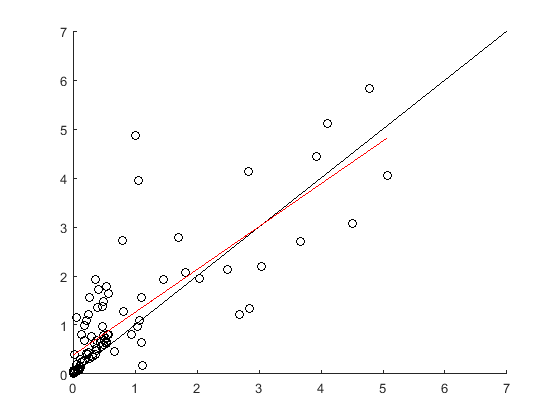

[p,S]=polyfit(FR_all(:,3),FR_all(:,4),1);
[y_fit,delta]=polyval(p,FR_all(:,3),S);
plot(FR_all(:,3),y_fit,'r')

scatter(fr_z(:,3),fr_z(:,4),'k')
hold on
plot(-2:2,-2:2,'k')

hold off
scatter(fr_z(:,3),fr_z(:,5),'k')
hold on
plot(-2:2,-2:2,'k')

fitlm(fr_z(:,3),fr_z(:,4))
[p,S]=polyfit(fr_z(:,3),fr_z(:,4),1);
[y_fit,delta]=polyval(p,fr_z(:,3),S);
%plot(fr_z(:,3),y_fit,'r')

hab interaction zones

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
list_cells=num2str(ls('TT*unit*'));
makeEvsMatrix
load('R.mat');load('cups.mat')

timeStamps=cell2mat(R.TimeStamps)';
pos_ss=R.Pos.t;


    for r=1:length(timeStamps)
        q= pos_ss;
        val(r) = timeStamps(r); %value to find
    end
    
    closest_ind=ones(1,length(timeStamps));
    for aa=1:length(timeStamps)
        tmp = abs(q-val(aa));
        [idx idx]= min(tmp); %index of closest value
        closest_ind(aa)=idx;
    end
    
%numSess=input('how many sessions?');
numSess=5;
Start=ones(1,5);End=ones(1,5);
for aa=1:numSess
    Start(aa)=closest_ind(2*aa-1);
    End(aa)=closest_ind(2*aa);
end

evsGroups=zeros(1,length(pos_ss));
    for aa=1:numSess
        evsGroups(Start(aa):End(aa))=aa;
    end

posdata={R.Pos.x1 R.Pos.y1};
rad=12;
hk=[cups.lxc cups.lyc];
[~,Int_indsL] = pointsincircle(posdata,rad,hk);    
evsmatrixLInt=evs_matrix(:,Int_indsL);evsGroupsLInt=evsGroups(:,Int_indsL);

cup_evs=evsmatrixLInt(:,evsGroupsLInt==1);
for ii=1:length(list_cells)
    cup_means(ii)=(mean(movmean(cup_evs(ii,:),30)));
    cups_std(ii)=(mean(movstd(cup_evs(ii,:),30)));
end    
sessions={'hab','cups','fam1', 'nov', 'fam2'};
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        for k=1:length(sessions)
        thisSession=sessions(k);
        thisSession=cellstr(thisSession); 
        thisSession=char(thisSession);
        cd(thisSession)
        load('leftCup.mat');
        if isempty(leftCup{4})
            frL=NaN;
        else
        frL=leftCup{7}/(length(leftCup{4}));
        end
        frL_norm(j,k)=((leftCup{7}/(length(leftCup{4}))/10)-cup_means)/cups_std;
        cd ..
        end
        cd ..
        FRs{hh}=frL_norm;
        
    end
    clearvars('frL_norm', 'frL', 'holder','evs_matrix')
    cd ..
end

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
       list_cells=num2str(ls('TT*unit*'));
       load('hab_means.mat');load('hab_stds.mat')
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        for k=1:length(sessions)
        thisSession=sessions(k);
        thisSession=cellstr(thisSession); 
        thisSession=char(thisSession);
        cd(thisSession)
        load('leftCup.mat');load('rightCup.mat');
        if isempty(leftCup{4})
            frL=NaN;
        else
        frL=leftCup{7}/((leftCup{4}(end)-leftCup{4}(1)));
        end
        if isempty(rightCup{4})
           frR=NaN;
        else
        frR=rightCup{7}/((rightCup{4}(end)-rightCup{4}(1))/10);
        end
        
        frL_norm=(frL-(mean(means(j,:))))/mean(stds(j,:));
        frR_norm=(frR-mean(means(j,:)))/mean(stds(j,:));
        DiscriminationIndex(j,k)=(frL_norm-frR_norm)/(frL_norm+frR_norm);
        cd ..
        end
        cd ..
    end
    DiscriminationIndexes{hh}=DiscriminationIndex(:,:);
    clear DiscriminationIndex
    FR_all{hh}=frL_norm;
    cd ..
end

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
       list_cells=num2str(ls('TT*unit*'));
       load('hab_means.mat');load('hab_stds.mat')
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        for k=1:length(sessions)
        thisSession=sessions(k);
        thisSession=cellstr(thisSession); 
        thisSession=char(thisSession);
        cd(thisSession)
        load('leftCup.mat');
        if isempty(leftCup{4})
            frL=NaN;
        else
        frL=leftCup{7}/((leftCup{4}(end)-leftCup{4}(1))/10);
        end
        frL_norm(j,k)=(frL-mean(means(j,:)))/mean(stds(j,:));
       
        cd ..
        end
        cd ..
        FRintNorm{hh}=frL_norm;
        
    end
    clear frL_norm
    cd ..
end

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
       list_cells=num2str(ls('TT*unit*'));
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        for k=1:length(sessions)
        thisSession=sessions(k);
        thisSession=cellstr(thisSession); 
        thisSession=char(thisSession);
        cd(thisSession)
        load('leftCup.mat');
        if isempty(leftCup{4})
            frL=NaN;
        else
        frL=leftCup{7}/((leftCup{4}(end)-leftCup{4}(1))/10);
        end
        frL_norm(j,k)=(frL-mean(means(j,:)))/mean(stds(j,:));
       
        cd ..
        end
        cd ..
        FRintNorm{hh}=frL_norm;
        
    end
    clear frL_norm
    cd ..
end


% 
% for jj=1:length(sessions)
%     for hh=1:yy(1)
%     thisTime(hh,1:4)=allTimes(hh).timeinchamber(jj,1:4);
%     end
%     figure(1)
%     subplot(1,length(sessions),jj)
%     bar(mean(thisTime(:,1:3)));ylim([0 12000]); 
%    
% end

Bursts

% % for hh=1:yy(1)
% %     cd(animalIDs(hh,1:end))
% %     allFR(hh)=load('firingRate.mat');
% %     cd ..
% % end

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
       list_cells=num2str(ls('TT*unit*'));
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        load('Split')
        for k=1:length(sessions)
        thisSession=sessions(k);
        thisSession=cellstr(thisSession); 
        thisSession=char(thisSession);

        spkt=eval(strcat('Split.',thisSession,'.spkt'));
        maxisi=0.02; %20ms
        if length(spkt)<2
            bursting(j,k)=0;
        else
        [bursts,singlespikes] = burstfinder(spkt,maxisi);         
        bursting(j,k) = length(bursts)/(length(bursts)+length(singlespikes));
        end
        end
        cd ..
    end
    cd ..
    Bursts{hh}=bursting; 
    clear -bursting
end

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
       list_cells=num2str(ls('TT*unit*'));
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        load('Split')
        for k=1:length(sessions)
        thisSession=sessions(k);
        thisSession=cellstr(thisSession); 
        thisSession=char(thisSession);

        spkt=eval(strcat('Split.',thisSession,'.spkt'));
        isi{k,j}=diff(spkt);
        
        end
    cd ..
    end
    cd ..
    isi_all{hh}=isi;

    
end

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
       list_cells=num2str(ls('TT*unit*'));
    for j=1:length(list_cells)
        cd(list_cells(j,1:end))
        for k=1:length(sessions)
        thisSession=sessions(k);
        thisSession=cellstr(thisSession); 
        thisSession=char(thisSession);
        cd(thisSession)
        load('fieldStats.mat')        
        numFields(j,k) = fieldStats(1,1);
        peakRate(j,k) = fieldStats(1,2);
        info(j,k) = fieldStats(1,3);
        sparseness(j,k) = fieldStats(1,4);
        selectivity(j,k) = fieldStats(1,5);
        cd ..
        end
        cd ..

    end
    cd ..
    NumFields{hh}=numFields; PeakRate{hh}=peakRate; Info{hh}=info; Sparseness{hh}=sparseness;Selectivity{hh}=selectivity;
    clear -list_cells numFields peakRate info sparseness selectivity
end


FR_perChamber=vertcat(allFR(1).firingRate,allFR(2).firingRate,allFR(3).firingRate);

figure(2);
for j=1:length(sessions)
    subplot(1,length(sessions),j)
    for i=1:length(FR_perChamber)
        plot(FR_perChamber{i,j},'-o')
        hold on
    end
    axis([0.5 4 0 max(max(cell2mat(FR_perChamber)))+.5])
    title(sessions(j))
    
    hold off
end

Average Firing Rate

figure(3)
meanFR=cell(1,length(sessions));

ix=cellfun('isempty', FR_perChamber);
FR_perChamber(ix)={[NaN,NaN,NaN]};
for j=1:length(sessions)
    leftmean=ones(length(FR_perChamber),1);
    centermean=ones(length(FR_perChamber),1);
    rightmean=ones(length(FR_perChamber),1);
    for i=1:length(FR_perChamber)
          leftmean(i)=FR_perChamber{i,j}(1,1);
          centermean(i)=FR_perChamber{i,j}(1,2);
          rightmean(i)=FR_perChamber{i,j}(1,end);
    end
    leftmean=nanmean(leftmean);
    centermean=nanmean(centermean);
    rightmean=nanmean(rightmean);
    meanFR{1,j}=[leftmean centermean rightmean];
    subplot(1,length(sessions),j)
    bar(meanFR{1,j})
    axis([0.5 4 0 max(cell2mat(meanFR))+.5])
    title(sessions(j))
    %suptitle('Average Firing Rate per Chamber')
end

## Firing Rate in Interaction Zone

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
    allLspikes(hh)=load('spikesinLIntZone');
    allRspikes(hh)=load('spikesinRIntZone');
    allLtime(hh)=load('timeinLIntZone');
    allRtime(hh)=load('timeinRIntZone');
cd ..
end

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
    allLFR{hh}=allLspikes(hh).spikesinLIntZone(:,:)./(allLtime(hh).timeinLIntZone(:,:)./100);
    allRFR{hh}=allRspikes(hh).spikesinRIntZone(:,:)./(allRtime(hh).timeinRIntZone(:,:)./100);
cd ..
end

FR_LInt=vertcat(allLFR{1},allLFR{2},allLFR{3});
%FR_LInt(isnan(FR_LInt))=[];
FR_RInt=vertcat(allRFR{1},allRFR{2},allRFR{3});
ts_RInt=vertcat(allRtime(1).timeinRIntZone(1,:),allRtime(2).timeinRIntZone(1,:),allRtime(3).timeinRIntZone(1,:));
ts_LInt=vertcat(allLtime(1).timeinLIntZone(1,:),allLtime(2).timeinLIntZone(1,:),allLtime(3).timeinLIntZone(1,:));

figure()
subplot(2,2,1)
bar(nanmean(ts_LInt)/100,'k');title('Time in Novel Zone');hold off
subplot(2,2,2)
bar(nanmean(ts_RInt)/100,'k');title('Time in Familiar Zone');hold off
subplot(2,2,3)
plot(FR_LInt','-o'); hold on; plot(nanmean(FR_LInt),'k','linewidth',3);title('Firing Rate Novel');hold off
subplot(2,2,4)
plot(FR_RInt','-o'); hold on; plot(nanmean(FR_RInt),'k','linewidth',3);title('Firing Rate Familiar');hold off

## Find Cells that change FR for novel animals

think about a better way to do this?

for uu=1:length(FR_LInt)
    deltaLInt(uu,1)=-(FR_LInt(uu,3)-FR_LInt(uu,4));
end
deltaL_devs=std(deltaLInt);
posMod_inds=find(deltaLInt>0);
negMod_inds=find(deltaLInt<0);
veryposMod_inds=find(deltaLInt>deltaL_devs);
verynegMod_inds=find(deltaLInt<-deltaL_devs);

for uu=1:length(FR_RInt)
    deltaRInt(uu,1)=-(FR_RInt(uu,3)-FR_RInt(uu,5));
end

deltaR_devs=std(deltaRInt);
RposMod_inds=find(deltaRInt>0);
RnegMod_inds=find(deltaRInt<0);
RveryposMod_inds=find(deltaRInt>deltaL_devs);
RverynegMod_inds=find(deltaRInt<-deltaL_devs);


## What happens to firing over the novel vs familiar sessions?

list_cells=num2str(ls('TT*unit*'));
sessions={'cups', 'fam1', 'nov', 'fam2'};
for i= 1:length(list_cells)    
    thisCell=list_cells(i,1:end);
    cd(thisCell)
    for j=1:length(sessions)
        thisSession=sessions(j);
        thisSession=cellstr(thisSession);
        thisSession=char(thisSession);
        cd(thisSession)
        load('rightCup.mat')
        post=rightCup{4};
        ts=rightCup{3};
        %find individual trials by finding breaks in post
        diffPost=diff(post); breakInds=diffPost>(mode(diffPost)+0.01);%add a little buffer to this since timestamps aren't perfect
        trials=(find(breakInds==1));trialInds=find(diff(trials)>4);trials=trials(trialInds);
        %trial starts are the odds in trialStarts, trial ends are the evens
        trialStart=trials(1:2:length(trials));trialEnd=trials(2:2:length(trials));
        numTrials=length(trialEnd);
        for tr=1:numTrials
            Start=trialStart(tr);End=trialEnd(tr);
            thisTrial_post{tr}=post(Start:End);
            thisTrial_spk_ind=find(ts>post(Start)&ts<post(End));
            thisTrial_spk{tr}=ts(thisTrial_spk_ind);
        end
        
       % note this could be zero if you wished
        markerSize = 12;
        
       
        figure(i)
        for tr = 1:numTrials
            spikesT = thisTrial_spk{tr}-thisTrial_post{tr}(1,1);
            TrialS=thisTrial_post{tr}(1,1);
            TrialLength=(thisTrial_post{tr}(end,1)-TrialS);
            convFact=1/TrialLength;
            trialMarks=[0 TrialLength];
            spikesT_norm= convFact*spikesT;
            yVals = tr + 0*spikesT;  % offset by one vertically for each trial
            subplot(1,length(sessions),j)
            plot(spikesT_norm, yVals, 'r.', 'markerSize', markerSize);
            hold on
            axis([-.25 1.25 0 length(trialStart)])
            title(thisSession)
            
        end

        
        cd ..
    end
    fig=figure(i);
    savefig('normRasters')
    close all
    cd ..
end

## Correlations between sessions

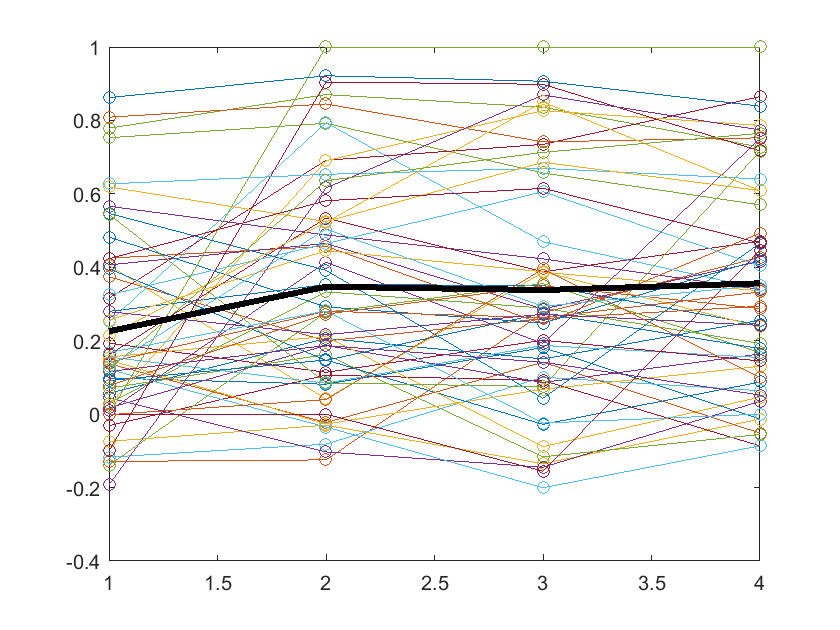

for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
    pop{hh}=load('pop_corr.mat');
cd ..
end

 allpops=vertcat(pop{1,1}.pop_corr,pop{1,2}.pop_corr,pop{1,3}.pop_corr);%,pop{1,4}.pop_corr,pop{1,5}.pop_corr);
 figure()
 plot(allpops','-o');hold on;plot(mean(allpops),'k','lineWidth',3);hold off

%%correlation confusion matrix
 for hh=1:yy(1)
cd(animalIDs(hh,1:end))
 
list_cells=num2str(ls('TT*unit*'));
sessions={'hab', 'cups', 'fam1', 'nov' ,'fam2'};

for ii=1:length(list_cells)
    load('corr_mat')
    
        for jj=1:length(sessions)
        %%compute correlations for each session vs another, this should be
        %%a 5x5 matrix
        for kk=1:length(sessions)
            [r]=corrcoef(corr_mat{ii,jj},corr_mat{ii,kk});
            thiscorr(1,kk)=r(2);
        end
        corrs(jj,:)=thiscorr;
        end
        
%         imagesc(corrs); % plot the matrix
%         set(gca, 'XTick', 1:ii); % center x-axis ticks on bins
%         set(gca, 'YTick', 1:ii); % center y-axis ticks on bins
%         set(gca, 'XTickLabel', sessions); % set x-axis labels
%         set(gca, 'YTickLabel', sessions); % set y-axis labels
%         Title=strcat('Cell',num2str(ii));
%         title(Title, 'FontSize', 14); % set title
%         colormap('jet'); % set the colorscheme
%         colorbar; % enable colorbar
        
        all_corrs(:,:,ii)=corrs;


end
        %cc(:,:,hh)=all_corrs;
        corrs_mean(:,:,hh)=mean(all_corrs,3);
        ac{hh}=all_corrs;
        clear all_corrs
        cd ..
end


all_means=mean(corrs_mean,3);
all_means(all_means==1)=NaN;
heatmap(all_means,'CellLabelColor','none'); % plot the matrix
%set(gca, 'XTick', 1:ii); % center x-axis ticks on bins
%set(gca, 'YTick', 1:ii); % center y-axis ticks on bins
ax=gca;
ax.XData=sessions;ax.YData=sessions;
%title('Mean Correlation Coefficients', 'FontSize', 14); % set title
colormap('viridis'); % set the colorscheme
colorbar; caxis([0 .5])% enable colorbar

## Field Properties

 for hh=1:yy(1)
    cd(animalIDs(hh,1:end))
    %list_cells=num2str(ls('TT*unit*
    pop{hh}=load('pop_corr.mat');
cd ..
end